エンドエフェクタ，対象物体，およびC-Closure Objectの視覚化

パラメータの設定

%clear

file_name = '../../img/test_loop_002.png'; % 対象物体となる画像ファイル(png)
robot_r = 5; % エンドエフェクタの半径
dc = 60; % エンドエフェクタ間距離
search_interval = 1; % C-ClosureObjectを生成するときの細かさを設定(0.1~1.0を推奨)
theta = deg2rad(0);

%potision_mat = [0, -dc/2, 0.0; ...
%                0, dc/2, 0.0;]; % エンドエフェクタの位置

potision_mat = [0, 0.0, 0.0]; % エンドエフェクタの位置


% 以下いじらないことを推奨
dots_spacing = 1.0;
robot_corners = 24; % エンドエフェクタの円の細かさ設定(defaultは24で円を24角形として近似して計算)
delta = 10^-6;
large_value = 10^12;
Threshold = search_interval/(fix(sqrt(2)*(10^10))/(10^10));

addpath('../../func','-end')
addpath('../../class','-end')

エンドエフェクタ，対象物体，およびC-Closure Objectの点群を作成

% make robot's boundary
s_x = (robot_r-search_interval)*cos(transpose(1:robot_corners)*2*pi/robot_corners);
s_y = (robot_r-search_interval)*sin(transpose(1:robot_corners)*2*pi/robot_corners);

% make object's boundary
object = get_object2d(file_name,dots_spacing);

% make C-Closure Object
c_cls = get_C_closure_object2d(file_name,robot_r,robot_corners,dots_spacing,search_interval);

       15824



各角度thetaごとの対象物体とC-Closure Objectの輪郭点を計算

workingspaceの表示

% trans_object
tf_0 = [cos(theta), sin(theta), 0.0, 0.0; ...
    -sin(theta), cos(theta), 0.0, 0.0; ...
    0.0, 0.0, 1.0, 0.0; ...
    0, 0, 0, 1.0];
tform0 = affine3d(tf_0);
object_t = pctransform(object,tform0);
object_t = pointCloud(round([object_t.Location(:,1),object_t.Location(:,2),object_t.Location(:,3)],10^10));
Threshold = dots_spacing/(fix(sqrt(2)*(10^10))/(10^10));
%object_shp = alphaShape(double(object_t.Location(:,1)),double(object_t.Location(:,2)),Threshold);
%[~,object_b] = boundaryFacets(object_shp);

object_shp_out = alphaShape(double(object_t.Location(:,1)),double(object_t.Location(:,2)),Threshold,'HoleThreshold',10^12);
object_shp_all = alphaShape(double(object_t.Location(:,1)),double(object_t.Location(:,2)),Threshold);

[~,object_out_b] = boundaryFacets(object_shp_out);
[~,object_all_b] = boundaryFacets(object_shp_all);

object_in_b = object_all_b(~ismember(object_all_b,object_out_b,'rows'),:);

object_poly_in = scale(polyshape(transpose(object_in_b(:,1)),transpose(object_in_b(:,2)),'Simplify',true),1+delta,[0,0]);

object_poly_out = scale(polyshape(transpose(object_out_b(:,1)),transpose(object_out_b(:,2)),'Simplify',true),1-delta,[0,0]);


object_poly = xor(object_poly_in,object_poly_out);

% trans_c_closure_object
pointclouds = PointClouds;
len = size(potision_mat,1);

for i= 1 : len
    tf_tran = [cos(theta), sin(theta), 0.0, 0.0; ...
            -sin(theta), cos(theta), 0.0, 0.0; ...
            0.0,  0.0, 1.0, 0.0; ...
            potision_mat(i,1), potision_mat(i,2), 0, 1.0];
    tf_tran = affine3d(tf_tran);

    pc_location_str = strcat('Location',sprintf('%02d',i));
    pc_shp_all_str = strcat('shp_all',sprintf('%02d',i));
    pc_shp_out_str = strcat('shp_out',sprintf('%02d',i));
    pc_poly_str = strcat('poly',sprintf('%02d',i));

    pointclouds.addprop(pc_location_str);
    pointclouds.addprop(pc_shp_all_str);
    pointclouds.addprop(pc_shp_out_str);
    pointclouds.addprop(pc_poly_str);
    
    pointclouds.(genvarname(['Location',sprintf('%02d',i)])) = pctransform(c_cls, tf_tran);
    pointclouds.(genvarname(['shp_all',sprintf('%02d',i)])) = alphaShape(pointclouds.(genvarname(['Location',sprintf('%02d',i)])).Location(:,1:2),Threshold);
    pointclouds.(genvarname(['shp_out',sprintf('%02d',i)])) = alphaShape(pointclouds.(genvarname(['Location',sprintf('%02d',i)])).Location(:,1:2),Threshold,'HoleThreshold',10^12);
    
    [~,c_cls_out_b] = boundaryFacets(pointclouds.(genvarname(['shp_out',sprintf('%02d',i)])));
    [~,c_cls_all_b] = boundaryFacets(pointclouds.(genvarname(['shp_all',sprintf('%02d',i)])));
    c_cls_in_b = c_cls_all_b(~ismember(c_cls_all_b,c_cls_out_b,'rows'),:);
    c_cls_poly_in = scale(polyshape(transpose(c_cls_in_b(:,1)),transpose(c_cls_in_b(:,2)),'Simplify',true),1+delta,[0,0]);
    c_cls_poly_out = scale(polyshape(transpose(c_cls_out_b(:,1)),transpose(c_cls_out_b(:,2)),'Simplify',true),1-delta,[0,0]);
    
    pointclouds.(genvarname(['poly',sprintf('%02d',i)])) = xor(c_cls_poly_in,c_cls_poly_out);
end

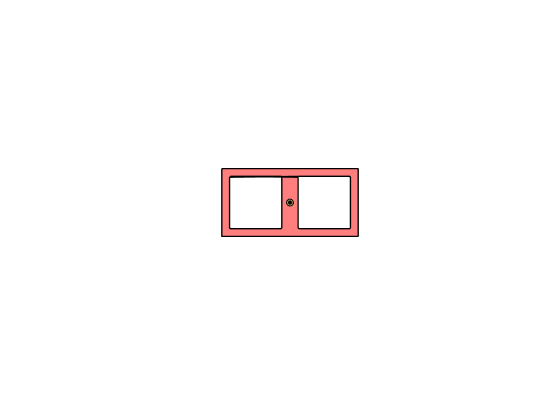


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 以下は出力設定 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on

plot(object_poly,'LineWidth',1.0,'FaceAlpha',0.5,'FaceColor','red','EdgeColor','black');

for i = 1 : len
    %robot
    fill(s_x+potision_mat(i,1),s_y+potision_mat(i,2),'green','LineStyle','-','FaceAlpha',0.3);
    scatter(potision_mat(i,1),potision_mat(i,2),10,'filled','MarkerFaceColor','black');
end

xlim([-200 200])
ylim([-200 200])
axis off
axis equal
xlim manual
ylim manual
hold off

C-Spaceの表示

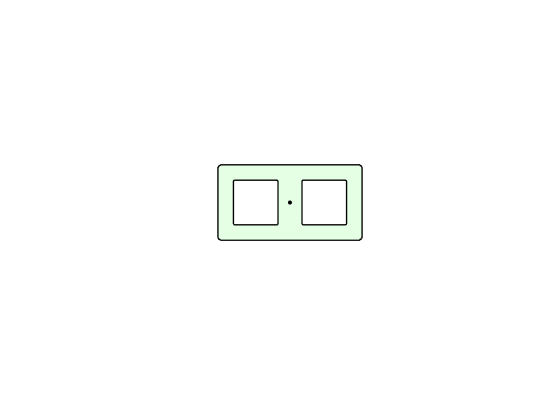

figure
hold on

for i = 1 : len
    % c_cls_obj
    plot(pointclouds.(genvarname(['poly',sprintf('%02d',i)])),'LineWidth',1.0,'FaceAlpha',0.1,'FaceColor','green','EdgeColor','black');
    scatter(potision_mat(i,1),potision_mat(i,2),10,'filled','MarkerFaceColor','black');
end

scatter(0,0,10,'filled','MarkerFaceColor','black');

xlim([-200 200])
ylim([-200 200])
axis off
axis equal
xlim manual
ylim manual
hold off